# 题目4：RGB转HSI

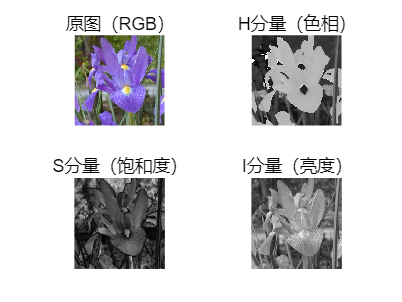

img_rgb = imread('./TestPhotos/flower.jpg');
img_rgb = im2double(img_rgb); 

% RGB转HSI
R = img_rgb(:,:,1);
G = img_rgb(:,:,2);
B = img_rgb(:,:,3);
I = (R + G + B) / 3; % 亮度分量

minRGB = min(img_rgb, [], 3);
S = 1 - minRGB ./ I; % 饱和度分量

theta = acos( (2*R - G - B) ./ (2*sqrt((R-G).^2 + (R-B).*(G-B)) + eps) ); % 计算色相
H = theta;
H(B > G) = 2*pi - H(B > G); % 调整色相范围到[0, 2π]
H = H / (2*pi); % 归一化到[0,1]

% 显示HSI分量
figure;
subplot(2,2,1), imshow(img_rgb), title('原图（RGB）');
subplot(2,2,2), imshow(H), title('H分量（色相）');
subplot(2,2,3), imshow(S), title('S分量（饱和度）');
subplot(2,2,4), imshow(I), title('I分量（亮度）');